# Introduction to Neural Networks (Lecture Edition)

## 1. Modeling image and text data 

### Some challenging unsolved biomedical problems 

#### A. Anomaly detection

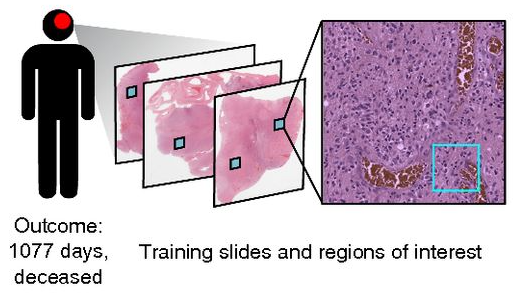

Image taken from Mobadersany et al., (2018). Predicting cancer outcomes from histology and genomics using convolutional networks. *Proceedings of the National Academy of Sciences*, *115*(13), E2970-E2979.

#### B.  Modeling EHR data for prognosis prediction

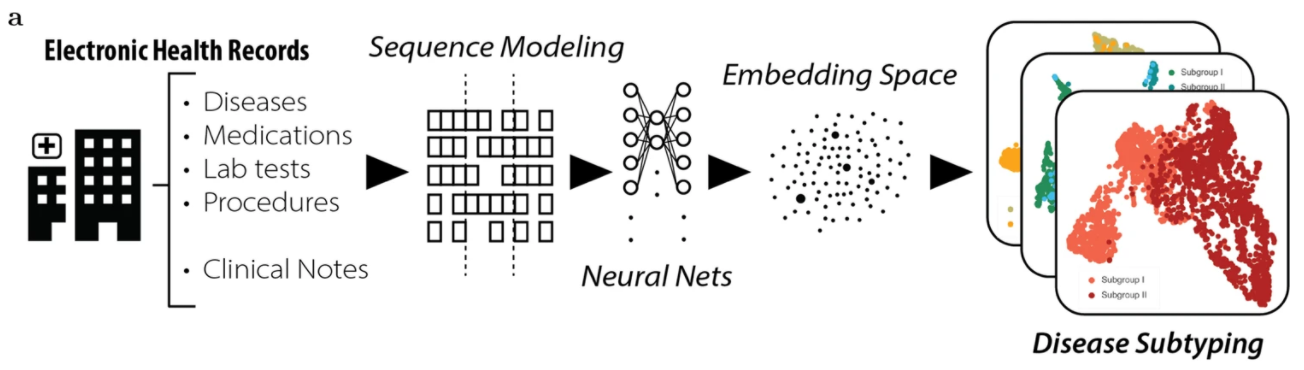

Image taken from Landi et al., (2020). Deep representation learning of electronic health records to unlock patient stratification at scale. *NPJ digital medicine*, *3*(1), 1-11.

### Why neural networks?

- No underlying model assumptions.

- Less of a need for human intervention.

- Generalizable: modular, transferrable, and customizable.

### Why not neural networks?

- High data requirements.

- Lack of model interpretibility.

- Training time.

## 2. Neural network primer

We'll briefly cover essential theory to get started trarining neural nets, including:

- Components

- Model training

- Model optimization

### The anatomy of a neural network 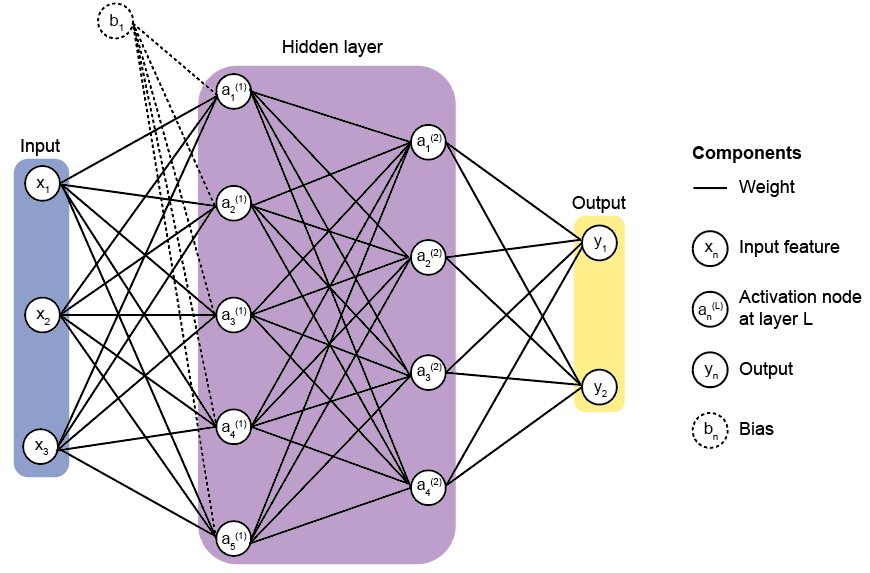

**Take-home message:** a neural network feeds data (**input layer**) into the **hidden layer** - a modular stack of equations that combines the data in a very non-linear way. The numbers returned in the **output layer** correspond to floating values (regression) or a probability of a given class (classification). 

### Model training

Training a neural network requires us to iterate 3 distinct phases for n times (**epochs**) until we reach a stable objective value (e.g., minimize cost). 

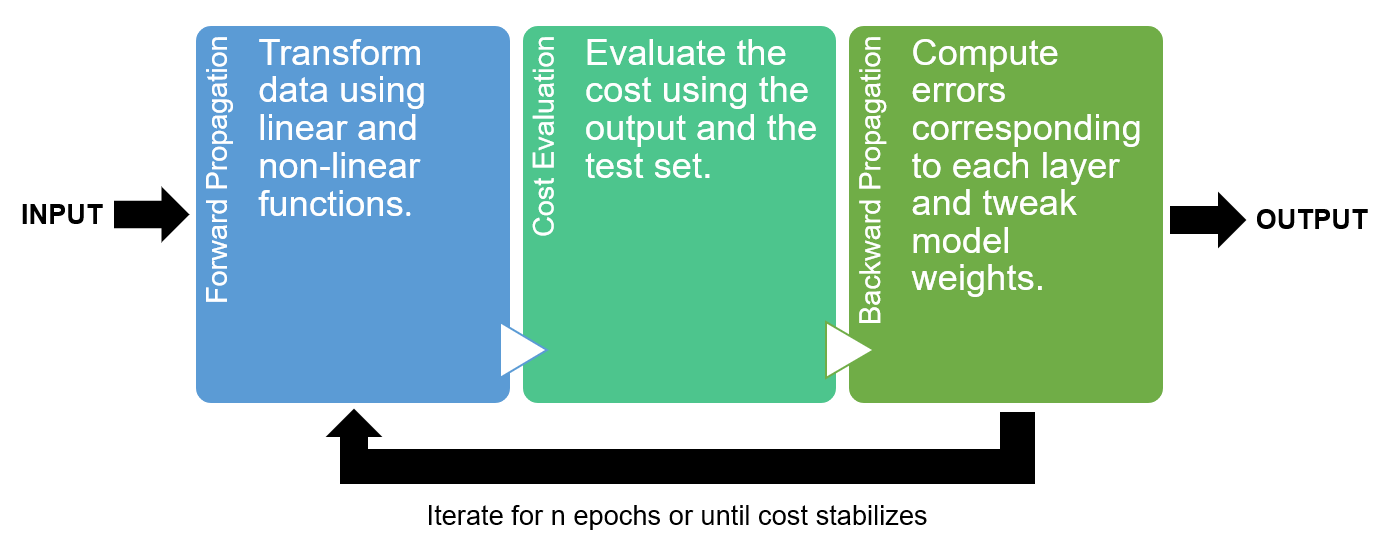

**The three phases are:**

- Forward propagation

- Solve the objective function

- Backward propagation and weight update

#### A. Forward propagation

**What is forward propagation?**

**Forward propagation** is the process of fitting a model with weights (analagous to regression coefficients). Then we transform the data with a non-linear **activation function**. 

One activation function is the sigmoid function. This function scales the data to assume a range of [0, 1], and is equivalent to performing **logistic regression**. The sigmoid distribution resulting from a normal distribution is shown below.

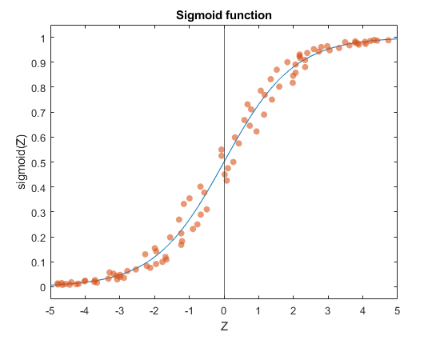

**Take-home: **This function is particularly useful to get probabilities for a **binary classification problem**. 

**Important note: **The activation function for a multi-class classification problem is called the **softmax** function, and this is a generalization of the sigmoid activation function. This is the activation function we will use in the lab section of this lecture.  

**How is this different from traditional ML?**

Fitting data to a linear equation (linear regression) or taking the sigmoid of the linear equation (logistic regression) are algorithms by their own right. However, **neural networks are modular**: we can stack these equations together into segments called **layers**.

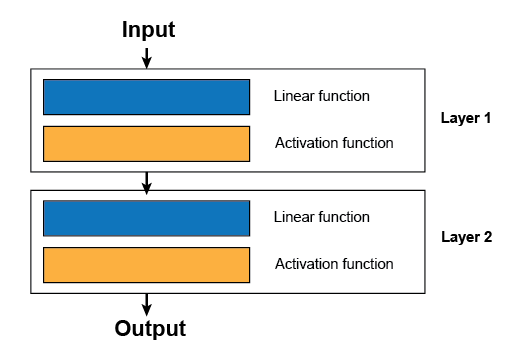

Shown in the figure above is a schematic of what goes on in a neural network layer. Each layer contains a linear function with an activation function. The training data is passed into layer 1, where it is linearly and non-linearly transformed. The resulting data computed from layer 1 is passed into layer 2, and is not seen by us. This is why this section is known as the hidden layer - we typically don't see the inner workings of the model.

#### B. Solve the objective function

Next, we need to see how right or wrong our model is by computing the objective value. In most cases, we're interested in computing the cost value. For regression, we typically use the **mean-squared error**. For binary classifiication, we use** cross-entropy**. 

#### C. Backward propagation and weight update with gradient descent

**What is backward propagation?**

**Motivation:** We just computed the global model error. However, to make our model learn better weights, we need to figure out how each weight contributed to this error. 

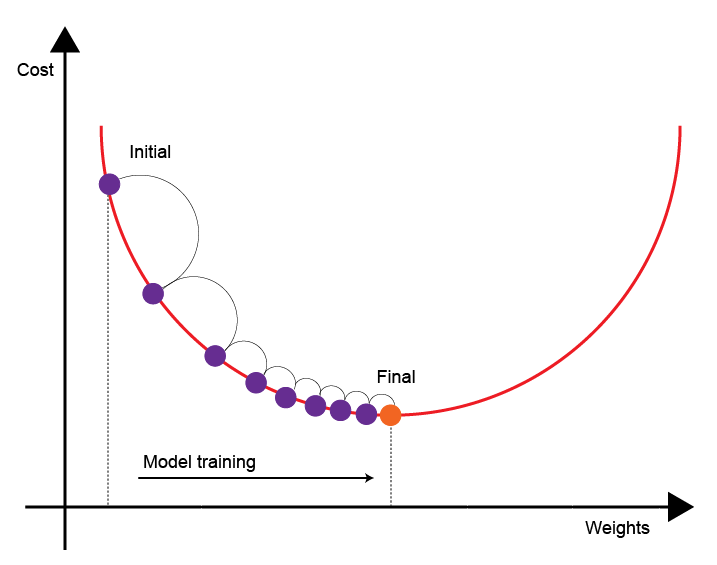

**Backward propagation** is the process of telling us where the errors occurred in forward propagation, starting from the cost value and working our way backwards. By computing the error contribution for each weight, we can use gradient descent to tweak individual weights to get a more accurate answer.

### Summary

We just went through one epoch of model training. In practice, we would (and we will) iterate this process several more times to get our final model.

To summarize the process of training a neural network,** the three phases of training involve:**

- **Forward propagation:** fitting the data with model weights across several layers.

- **Solve the objective function**, such as the model cost.

- **Backward propagation and weight update** to get a more accurate model in the next epoch.

## 3. Training shallow feedforward neural networks

To practice training neural networks, we'll train a **shallow neural network**: a neural network with few layers. Information is only fed into the next adjacent layer (and not back into previous layers), making this a **feedforward neural network**. 

- This is in contrast to **recurrent neural networks**, where information can travel back to the previous layer. This is beyond the scope of this lecture, but you can find additional information in the **appendix**. 

**Our task:** We'll focus on a binary classification problem to predict whether or not a patient has metastatic breast cancer, given some imaging data that has been engineering into 7 features. 

### Description of the dataset

This built-in MATLAB dataset can be called using the `load cancer_dataset `command, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. 

- The **input** is a matrix of 9 features from 699 biopsies. The **features** include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The **output** `cancerTargets` variable is a 2 x 699 matrix, where the first row corresponds to benign, and the the second row corresponds to malignant. 

### A. Load the breast cancer image classification dataset

Let's load the breast cancer image classification dataset. The MATLAB built-in functions process datasets where the features/target variables span the rows, while the observations span the columns.

clear all; 
load cancer_dataset.mat

X = cancerInputs;
Y = cancerTargets;

#### Splitting the data into training and validation sets

The data needs to be split into a training set and validation set. To save time, we created a function called `trainTestSplit` that automatically does that. 

**The docstring is provided below:**

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xval, Yval] = ...
    trainTestSplit(X', Y', ...
    trainingSize, randomstate);

Finally, we need to reformat the data for the deep learning toolbox. Everything will be transposed, and the output for classification needs to be a categorical data type.

% Re-format so the DLT can use the data
Xtrain = Xtrain';              Xval = Xval';
Ytrain = categorical(Ytrain'); Yval = categorical(Yval');

### B. Setting the shallow neural network architecture

Now, we need to specify the neural network architecture. We will store the network as an array called `layers`, which will contain several structures used for our downstream computations. 

Let's construct a real simple shallow neural network with one hidden layer containing two nodes. The output will be a matrix corresponding to the probability of the sample being benign or malignant. A network graph is shown below.

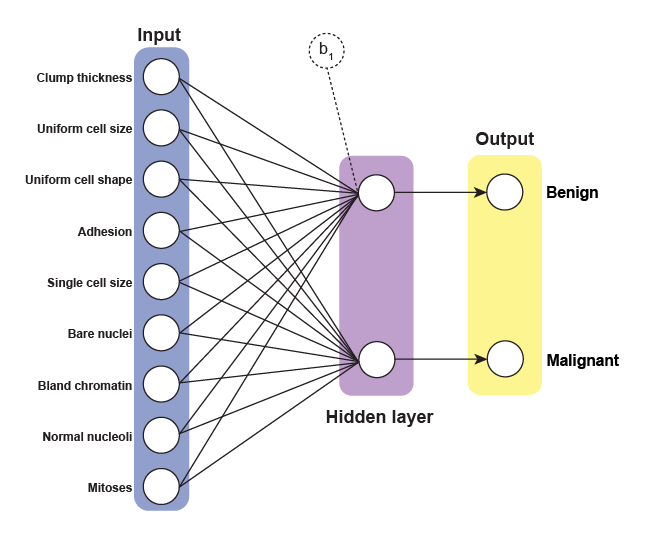

**There are 4 components we need to specify in the **`layer`** array:**

- **Input data layer**: the specific function differs on the data type inputed. For numerical data, the `sequenceInputLayer` is the appropriate function, which needs the number of features as the parameter.

- **Hidden layer architecture**: the specific architecture needed to design a feedforward neural network is the `fullyConnectedLayer`, which needs the number of activation nodes as the first parameter. The `WeightsInitializer` and `BiasInitializer` parameters tell the function how to initialize the parameters, using small random numbers from a normal distribution.

- **Activation function**: Between each `fullyConnectedLayer` is the activation function. The `softmaxLayer` is the activation function we will use, which is the generalization of the cross entropy function.

- **Classification layer** (optional): The `classificationLayer` transforms the values to their predicted labels.

% Specify neural network architecture
layers = [...
    
    sequenceInputLayer(size(X, 1)), ...          % Input data layer

    fullyConnectedLayer(10, ...                  % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                            % Activation function 
    
    fullyConnectedLayer(2, ...                   % Output layer with 2 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                            % Transform to probabilities
    
    classificationLayer ...                      % Label encode
]

layers =   6×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 9 dimensions
     2   ''   Fully Connected         10 fully connected layer
     3   ''   Softmax                 softmax
     4   ''   Fully Connected         2 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

### C. View the network structure with MATLAB's GUI

Let's view the network structure stored in the `layers` variable using the `analyzeNetwork` function.

analyzeNetwork(layers)

### D.Setting up the network hyperparameters

**Hyperparameters** are user-set parameters that will affect the model performance. Some examples we've seen so far are the number of nodes and number of layers in a network.

The `trainingOptions` function creates a model object that lets you feed in the hyperparameters into the neural network function. The specific arguments we will use are shown below, along with a description of what they do.

% Spcify hyperparameters for neural network
options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 200, ...                         % Maximum number of epochs to train algorithm
    'ValidationData', {Xval, Yval(1, :)}, ...     % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
);     

### F. Training the shallow neural network

Finally, let's train the neural network using the `trainNetwork` function, which allows us to train other deep neural network architectures. 

For more information on other neural networks you can train using this function, you can [read the documentation](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html).

[snn, trainingInfo] = trainNetwork(Xtrain, Ytrain(1, :), layers, options)

Training on single GPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:04 |       66.55% |       61.43% |       0.6872 |       0.6850 |          0.0100 |


|      30 |          30 |       00:00:06 |       66.55% |       61.43% |       0.5902 |       0.6156 |          0.0100 |


|      50 |          50 |       00:00:07 |       66.55% |              |       0.4746 |              |          0.0100 |


|      60 |          60 |       00:00:07 |       92.31% |       90.71% |       0.4064 |       0.4183 |          0.0100 |


|      90 |          90 |       00:00:08 |       96.78% |       96.43% |       0.2357 |       0.2393 |          0.0100 |


|     100 |         100 |       00:00:08 |       96.60% |              |       0.2036 |              |          0.0100 |


|     120 |         120 |       00:00:08 |       96.96% |       96.43% |       0.1636 |       0.1633 |          0.0100 |


|     150 |         150 |       00:00:09 |       97.14% |       96.43% |       0.1330 |       0.1301 |          0.0100 |


|     180 |         180 |       00:00:09 |       97.14% |       96.43% |       0.1172 |       0.1127 |          0.0100 |


|     200 |         200 |       00:00:10 |       97.14% |       97.14% |       0.1106 |       0.1054 |          0.0100 |


|======================================================================================================================|


snn =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


trainingInfo = struct with fields:
               TrainingLoss: [1×200 double]
           TrainingAccuracy: [1×200 double]
             ValidationLoss: [1×200 double]
         ValidationAccuracy: [1×200 double]
              BaseLearnRate: [1×200 double]
        FinalValidationLoss: 0.1054
    FinalValidationAccuracy: 97.1429


A window will pop up with the following plot as the model is trained in real time.

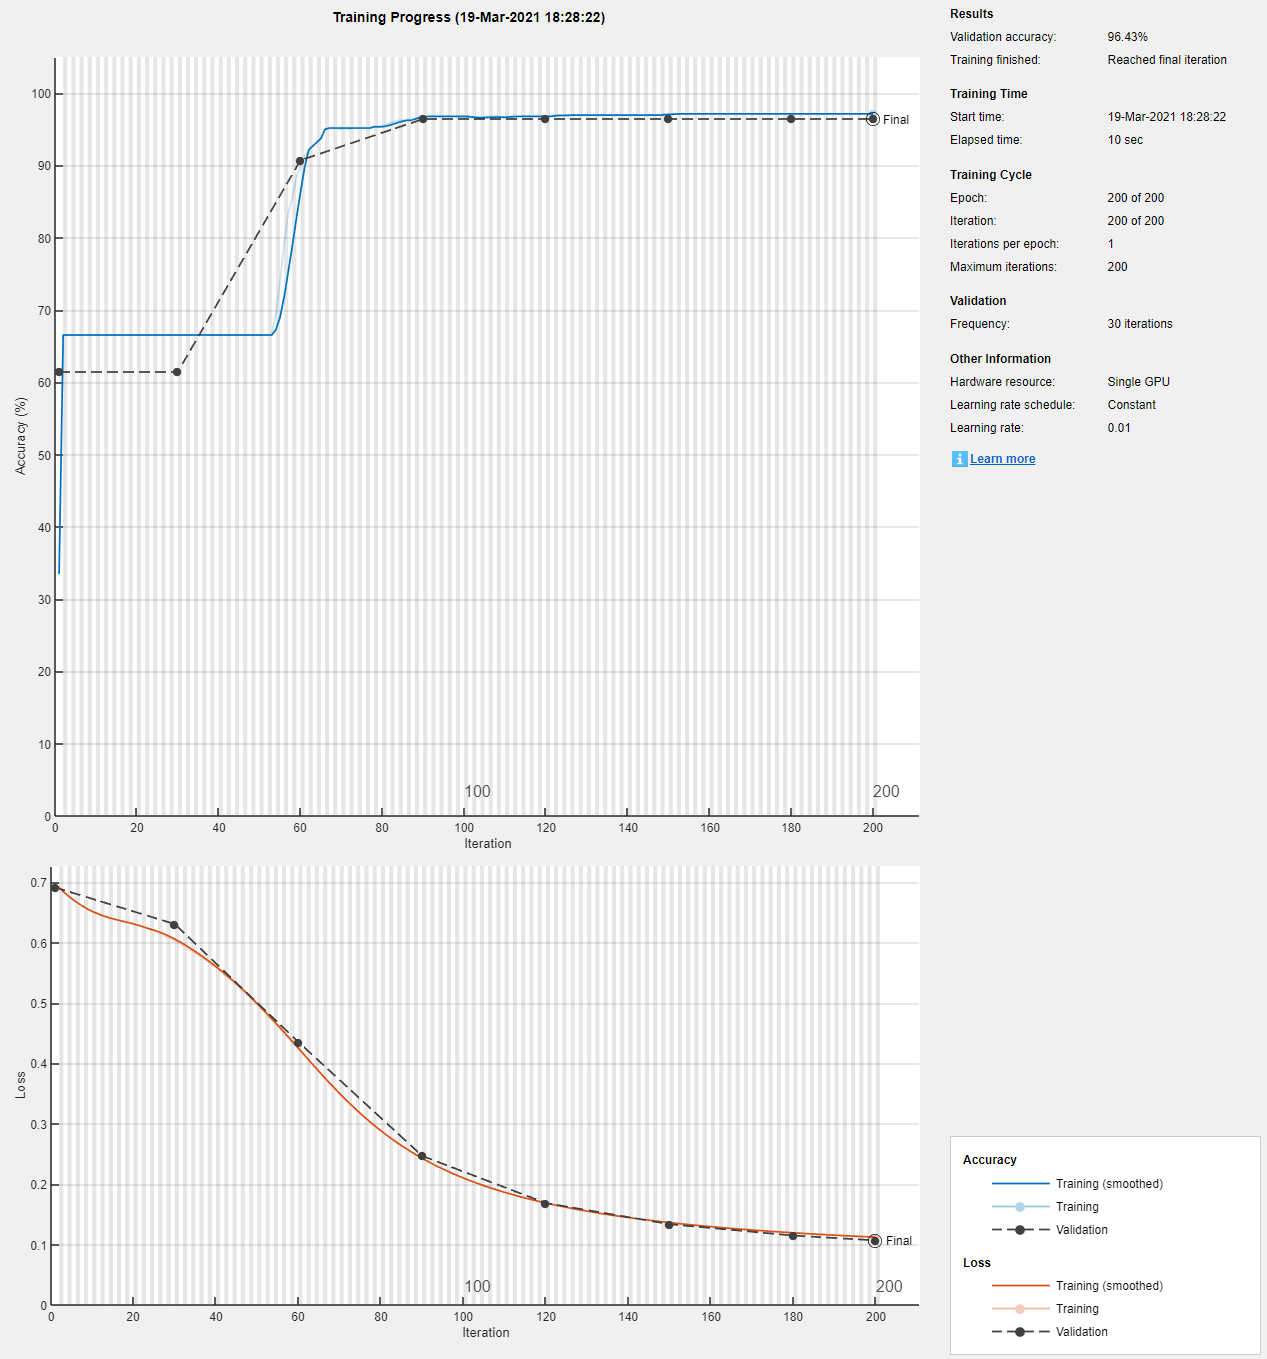

### G. Computing model predictions and evaluating model performance

To make predictions using the deep neural network model, we can use the built-in `predict` function, which returns the class probabilites.

ypred_snn = classify(snn, Xval)

ypred_snn = 1×140 categorical array
     0      0      1      0      1      1      0      0      1      1      0      0      1      0      0      1      1      0      0      1      0      0      0      1      1      1      0      1      0      0      1      1      0      1      1      0      0      1      1      1      0      1      1      1      1      1      1      0      1      0      1      1      1      1      0      1      1      0      1      1      1      1      0      1      0      0      1      1      1      1      0      0      0      1      1      1      0      1      0      1      1      0      1      0      0      0      0      1      0      1      1      1      1      1      1      1      1      0      1      0      1      1      1      1      1      1      1      0      1      1      1      1      0      1      0      0      0      1      0      0      1      1      1      0      1      1      0      1      1      1      1      1      1      0      0      0      1      

### H. Plotting model metrics 

#### Confusion matrix

To evaluate the average and individual class accuracies, we can use a confusion matrix.

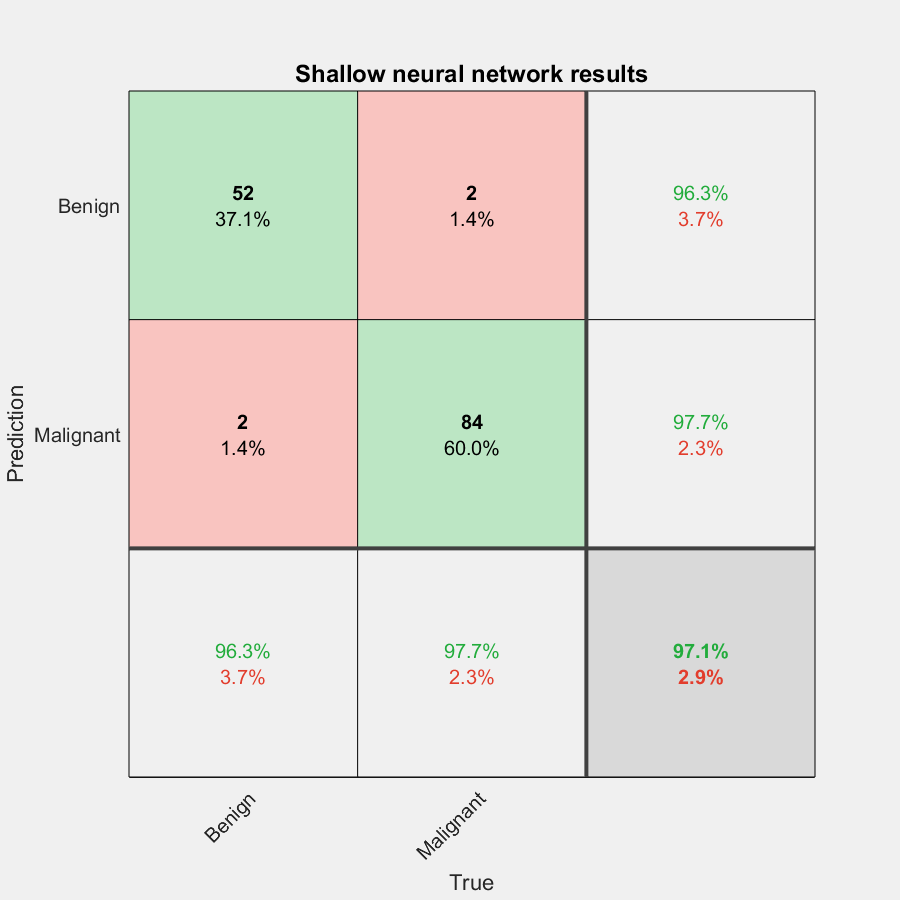

figure;
plotconfusion(ypred_snn, Yval(1, :));
title("Shallow neural network results");
xlabel("True"); ylabel("Prediction");
xticklabels(["Benign", "Malignant"]);
yticklabels(["Benign", "Malignant"]);

## 4. Training deep feedforward neural networks

We'll train a **deep neural network**: a neural network with many layers. 

A general trend with deep neural networks is that the more nodes and more layers you add, the more accurate the model becomes. However, tradeoff is that this increases the computation time and the risk of overfitting.

### **A. Declare the model architecture**

Now, we need to specify the neural network architecture. We will store the network as an array called `layers`. We'll be constructing a deep neural network that has the following structure:

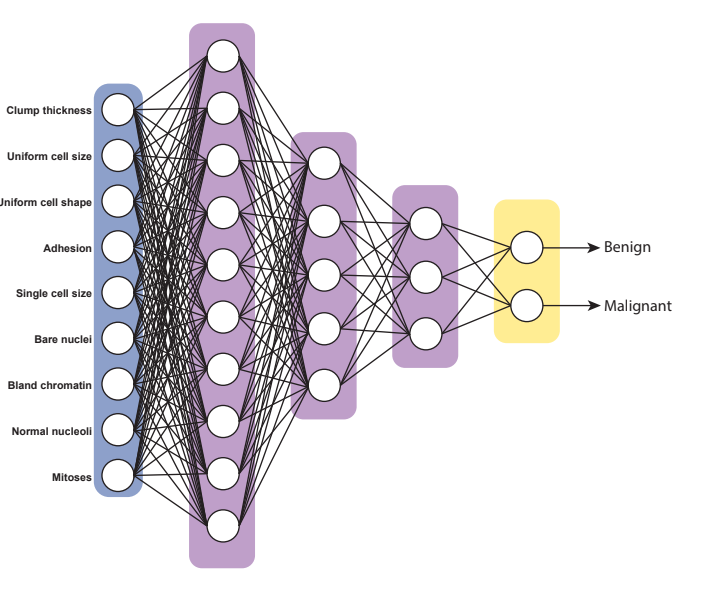

**Create the layers structure.**

% Specify neural network architecture
layers = [...
    
    sequenceInputLayer(size(X, 1)), ...            % Input data layer

    fullyConnectedLayer(10, ...                    % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                              % Activation function 1
    
    fullyConnectedLayer(5, ...                     % Hidden layer 2 with 5 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                              % Activation function 2
    
    fullyConnectedLayer(3, ...                     % Hidden layer 3 with 3 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                              % Activation function 3
    
    fullyConnectedLayer(2, ...                     % Output layer with 2 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                              % Transform to probabilities
    
    classificationLayer ...                        % Label encode
]

layers =   10×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 9 dimensions
     2   ''   Fully Connected         10 fully connected layer
     3   ''   Softmax                 softmax
     4   ''   Fully Connected         5 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Fully Connected         3 fully connected layer
     7   ''   Softmax                 softmax
     8   ''   Fully Connected         2 fully connected layer
     9   ''   Softmax                 softmax
    10   ''   Classification Output   crossentropyex

### B.Setting up the network hyperparameters

Next, we have to specify the model hyperparameters. We'll use the same hyperparameters we previously specified.

% Spcify hyperparameters for neural network
options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 200, ...                         % Maximum number of epochs to train algorithm
    'ValidationData', {Xval, Yval(1, :)}, ...     % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
);                

### C. Training the deep neural network

Finally, let's train the neural network using the `trainNetwork` function.

[dnn, trainingInfo] = trainNetwork(Xtrain, Ytrain(1, :), layers, options)

Training on single GPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |       33.45% |       61.43% |       0.6937 |       0.6891 |          0.0100 |


|      30 |          30 |       00:00:06 |       66.55% |       61.43% |       0.6386 |       0.6795 |          0.0100 |


|      50 |          50 |       00:00:06 |       66.55% |              |       0.6373 |              |          0.0100 |


|      60 |          60 |       00:00:07 |       66.55% |       61.43% |       0.6370 |       0.6708 |          0.0100 |


|      90 |          90 |       00:00:08 |       66.55% |       61.43% |       0.5349 |       0.5558 |          0.0100 |


|     100 |         100 |       00:00:08 |       66.55% |              |       0.4313 |              |          0.0100 |


|     120 |         120 |       00:00:09 |       97.50% |       97.14% |       0.2530 |       0.2534 |          0.0100 |


|     150 |         150 |       00:00:10 |       97.85% |       96.43% |       0.1451 |       0.1496 |          0.0100 |


|     180 |         180 |       00:00:11 |       97.85% |       97.14% |       0.1131 |       0.1219 |          0.0100 |


|     200 |         200 |       00:00:11 |       98.03% |       97.14% |       0.1032 |       0.1151 |          0.0100 |


|======================================================================================================================|


dnn =   SeriesNetwork with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


trainingInfo = struct with fields:
               TrainingLoss: [1×200 double]
           TrainingAccuracy: [1×200 double]
             ValidationLoss: [1×200 double]
         ValidationAccuracy: [1×200 double]
              BaseLearnRate: [1×200 double]
        FinalValidationLoss: 0.1151
    FinalValidationAccuracy: 97.1429


### D. Computing model predictions and evaluating model performance

To make predictions using the deep neural network model, we can use the built-in `predict` function, which returns the class probabilites.

ypred_dnn = classify(dnn, Xval)

ypred_dnn = 1×140 categorical array
     0      0      1      0      1      1      0      0      1      1      0      0      1      0      0      1      1      0      0      1      0      0      0      1      1      1      0      1      0      0      0      1      0      1      1      0      0      1      1      1      0      1      1      1      1      1      1      0      1      0      1      1      1      1      0      1      1      0      1      1      1      1      0      1      0      0      1      1      1      1      0      0      0      1      1      0      0      1      0      1      1      0      1      0      0      0      0      1      0      1      1      1      1      1      1      1      1      0      1      0      1      1      1      1      1      1      1      0      1      1      1      1      0      1      0      0      0      1      0      0      1      1      1      0      1      1      0      1      1      1      1      1      1      0      0      0      1      

### E. Plotting model metrics 

#### Confusion matrix

To evaluate the average and individual class accuracies, we can use a confusion matrix.

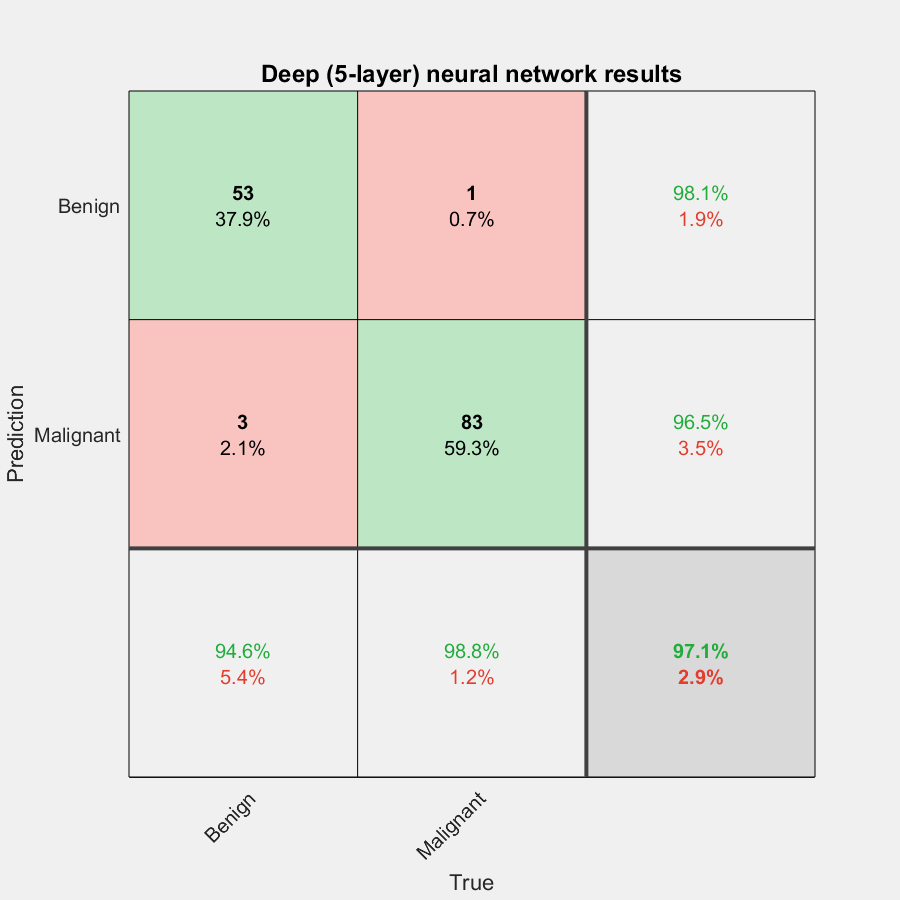

figure;
plotconfusion(ypred_dnn, Yval(1, :));
title("Deep (5-layer) neural network results");
xlabel("True"); ylabel("Prediction");
xticklabels(["Benign", "Malignant"]);
yticklabels(["Benign", "Malignant"]);

## 5. Model optimization

While neural networks are really popular for artificial intelligence research and applications, they can be difficult to train and computationally intensive. We'll discuss common issues encountered when training neural network and potential strategies to address these issues.

### A. Regularization

MATLAB's Deep Learning Toolbox currently only supports L2 (Ridge) regularization as a built-in function using the `trainingOptions` object. To specify the tuning parameter to be 1E-5, we can use the following syntax:

### B. Dropout

Overfitting is a result of a model fitting to noise in the dataset, rather than the real signal. Instead of constraining the model, [Srivastava et al., 2014](https://www.cs.toronto.edu/~hinton/absps/JMLRdropout.pdf) suggested to do something pretty clever: randomly and temporarily remove activation nodes in the hidden layer (essentially, set it to 0 for a given epoch), along with the incoming and outgoing weights. 

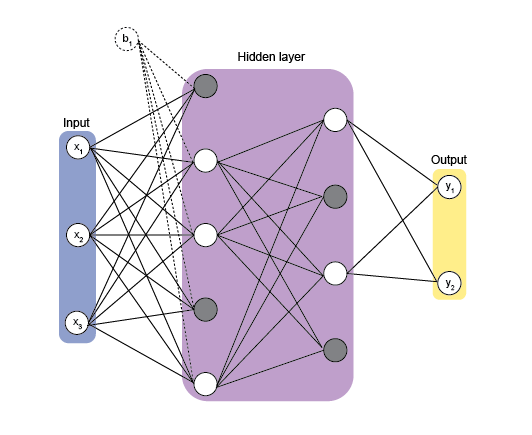

This is another form of regularization, in that the model is pruned during every epoch. It works because during the pruning process, we eliminate relationships between nodes that may be co-dependent, and causing errors in the model by random chance. By making the model more sparse, it learns the more important weights better, and increases its robustness.

To add dropout layers in the model built from the `trainNetwork` function, we can specify this as a `dropoutLayer` object when building our `layers` array:

### C. Parallel computing

#### Multiple CPUs

When working with really large datasets, computational efficiency becomes more important. One way to deal with more complex models or computing large datasets for any model is to run MATLAB with the [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html#scale-up-matlab-applications), which splits the computation process between different processing units if you have a multi-core machine.

To implement parallel processing with a shallow neural network, we can use the following snippet of code to use the parallel computing toolbox. 

#### D. Training with a GPU

The Parallel Computing Toolbox also allows us to run our code on a GPU if your local machine or computing cluster if available. 

Currently MATLAB only supports NVIDIA GPUs. To train a deep neural network using a GPU, MATLAB automatically detects and uses the `gpu` from the `ExecutationEnvironment` argument. 

However, if we want to use both the `gpu` and `cpu`, we can specify this argument to `parallel`.

Alternatively, we can specify which datasets we want to be fed into a GPU computation using the `gpuArray` function. If you do have a GPU, these arrays will automatically be detected for GPU use. 

Finally, if we want to use the `trainNetwork` function to train a deep neural network using a GPU, we can specify the GPU as a hyperparameter in the function. 

## Summary

We covered the basic theory and code from the [Deep Learning Toolbox](https://www.mathworks.com/help/deeplearning/getting-started-with-deep-learning-toolbox.html) for training and implementing feedforward neural networks to a cancer classification task (benign/malignant). Additionally, we discussed several strategies for optimizing model performance. 

## Appendix

### Built in MATLAB functions covered in this lesson

`analyzeNetwork:`           View the network structure.

`sequenceInputLayer: ` Create an input dataset structure. 

`fullyConnectedLayer:` Create an object that does a linear transformation.

`softmaxLayer:       ` Create an object that does a sigmoid transformation.

`classificationLayer:` Create an object that performs classification. 

`trainingOptions:    ` Create an object that stores model hyperparameters.

`trainNetwork`:                Train the neural network.

`classify:         `     Perform a classification prediction with a trained neural network.

`plotconfusion:      ` Plot a confusion matrix.

### List of custom functions

`trainTestSplit:     `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$dataset.

### Useful reading and references

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book is technical and dives deep into the theory. Recommended for intermediate to advanced level understanding.